Данные варианта

A = [-2, 0, -4, 2;
    0, 2, -2 ,4;
    -4, -2, 2, 0;
    2, 4, 0, 2];
B = [8; 6; 4; 2];
C = [2, 0, 0, 2;
    -1, 1, 1, 1];

x0 = [1; -4; 1; 1];
x1 = [2; 3; -1; 9];

Нахождение собственных чисел матрицы А

eA = eig(A);

Проверка наблюдаемости собственных чисел

Создание матрицы наблюдаемости и управляемости

V = obsv(A, C)

V =      2     0     0     2
    -1     1     1     1
     0     8    -8     8
     0     4     4     4
    48    64   -32    48
    -8    16     0    24
   128   384  -384   448
    64   128     0    96


rankV = rank(V)

rankV = 4


U = ctrb(A, B);
rankU = rank(U);

Ранговый критерий

I = eye(4);
rank([A - (-5.5583)*I; C]);
rank([A - (-0.9812)*I; C]);
rank([A - (3.1960)*I; C]);
rank([A - (7.3436)*I; C]);

rank([A - (-5.5583)*I, B]);
rank([A - (-0.9812)*I, B]);
rank([A - (3.1960)*I, B]);
rank([A - (7.3436)*I, B]);

Матрица гамма и матрица Y

G=[-2, 0, 0 ,0;
    0, -3, 0, 0;
    0, 0, -1, 3;
    0, 0, -3, -1];
A1 = -1*A;
Y1 = [1, 1;
    1, 1;
    1, 1;
    1, 1];
Y = [1, 1, 1, 1];
G1 = -1*G;


Решение уравнения сельвестра

BY = B*Y;
P = sylvester(A, G1, BY)

P =    -1.1818   -2.2356   -1.8397   -0.1433
   -1.2727   -1.1541   -0.1243    0.2266
   -0.8182   -1.4502   -1.2479    0.0454
    2.3636    2.2175    0.7994    1.2595


Вычисление матрицы регулятора

K = -Y*pinv(P)

K =    -1.7799   -1.1356    2.9626   -0.8990


Решение уравнения сельвестра

Y1C = Y1*C;
Q = sylvester(G, A1, Y1C)

Q =    -0.5909    0.8636   -0.4091   -1.3182
   -0.1964    0.3716   -0.2085   -0.8187
   -0.1289    0.0103   -0.3487   -0.7713
    0.3270   -0.4524    0.1498    0.1564


Вычисление матрицы регулятора

L = pinv(Q)*Y1

L =    -2.7273   -2.7273
   -3.4034   -3.4034
    6.2102    6.2102
   -3.6932   -3.6932


Матрица для модели

Построение графиков

a = out.x % 4

  timeseries

  Common Properties:
            Name: ''
            Time: [10001x1 double]
        TimeInfo: [1x1 tsdata.timemetadata]
            Data: [10001x4 double]
        DataInfo: 

b = out.e % 4

  timeseries

  Common Properties:
            Name: ''
            Time: [10001x1 double]
        TimeInfo: [1x1 tsdata.timemetadata]
            Data: [10001x4 double]
        DataInfo: 

c = out.y % 2

  timeseries

  Common Properties:
            Name: ''
            Time: [10001x1 double]
        TimeInfo: [1x1 tsdata.timemetadata]
            Data: [10001x2 double]
        DataInfo: 

d = out.u % 1

  timeseries

  Common Properties:
            Name: ''
            Time: [10001x1 double]
        TimeInfo: [1x1 tsdata.timemetadata]
            Data: [10001x1 double]
        DataInfo: 

plot(out.x.Time, out.x.Data(:,1), 'LineWidth', 2);
hold on;
plot(out.x1.Time,out.x1.Data(:,1), 'LineWidth', 2, 'LineStyle',':');
title('$x_{1}$','Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 15);
xlabel('Time, sec', 'Interpreter', 'latex', 'FontSize', 15);
legend("$x_{1}$(t)","$\hat{x}_{1}$(t)", "$x_{4}$", 'Interpreter', 'latex', 'FontSize', 15);

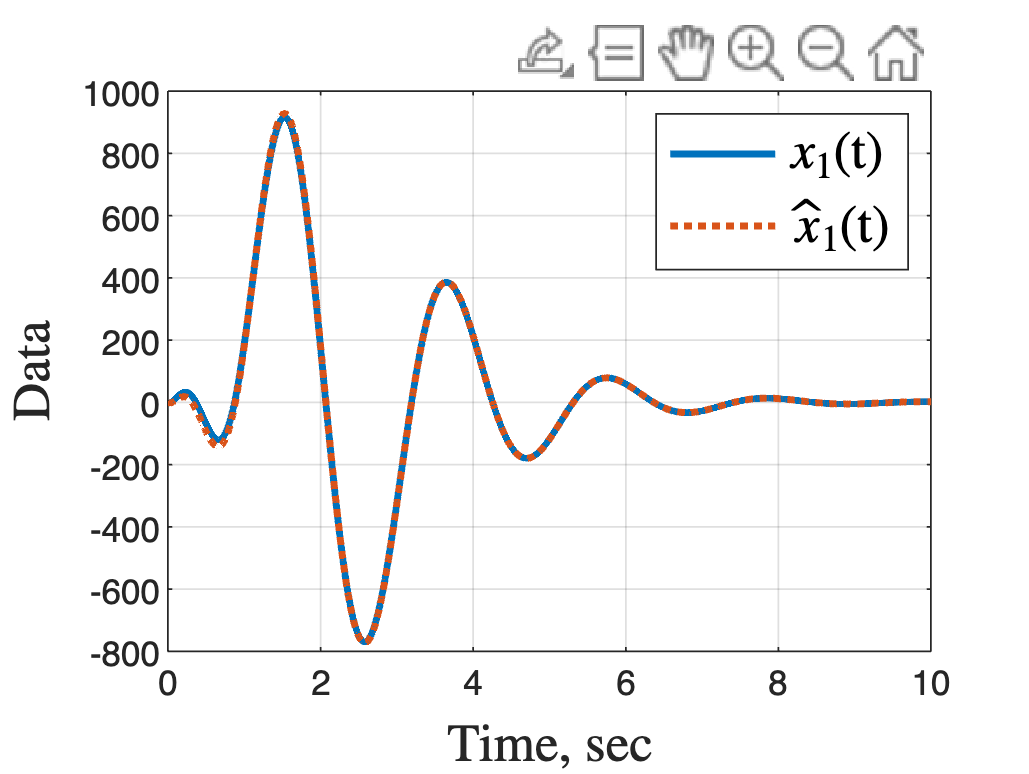

grid on;
hold off;

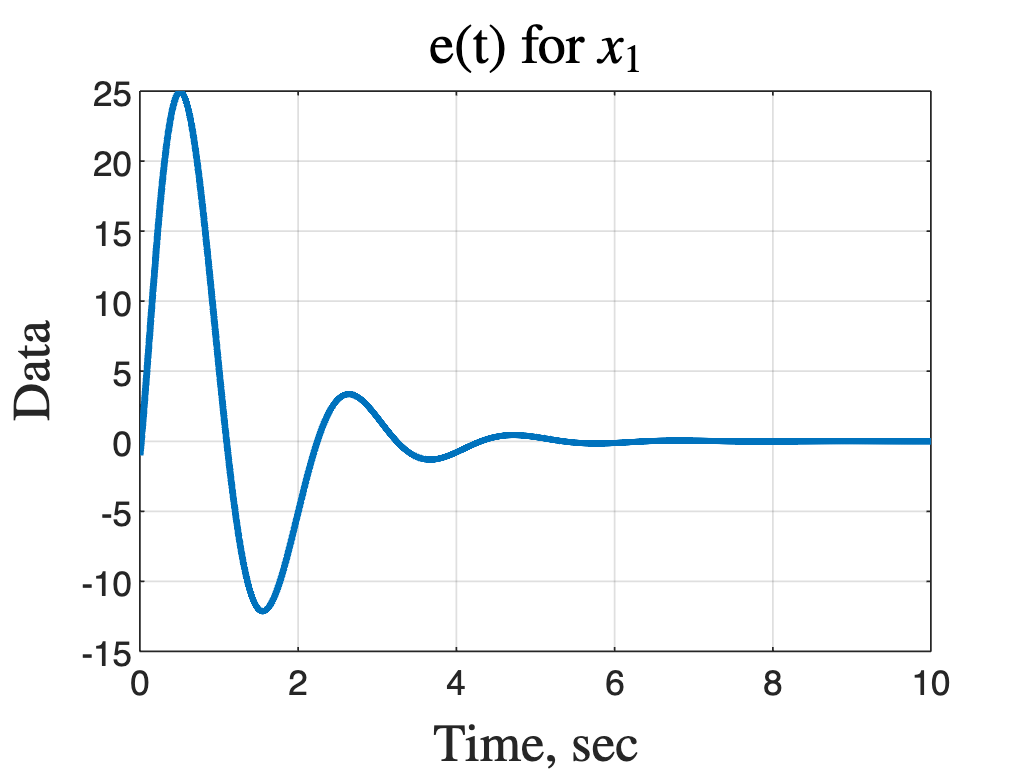



plot(out.e.Time,out.e.Data(:,1), 'LineWidth', 2);
title('e(t) for $x_{1}$','Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 15);
xlabel('Time, sec', 'Interpreter', 'latex', 'FontSize', 15);
grid on;
hold off;


plot(out.x.Time,out.x.Data(:,2), 'LineWidth', 2);
hold on;
plot(out.x1.Time,out.x1.Data(:,2), 'LineWidth', 2, 'LineStyle',':');
title('$x_{2}$','Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 15);
xlabel('Time, sec', 'Interpreter', 'latex', 'FontSize', 15);
legend("$x_{2}$(t)","$\hat{x}_{2}$(t)", "$x_{4}$", 'Interpreter', 'latex', 'FontSize', 15);

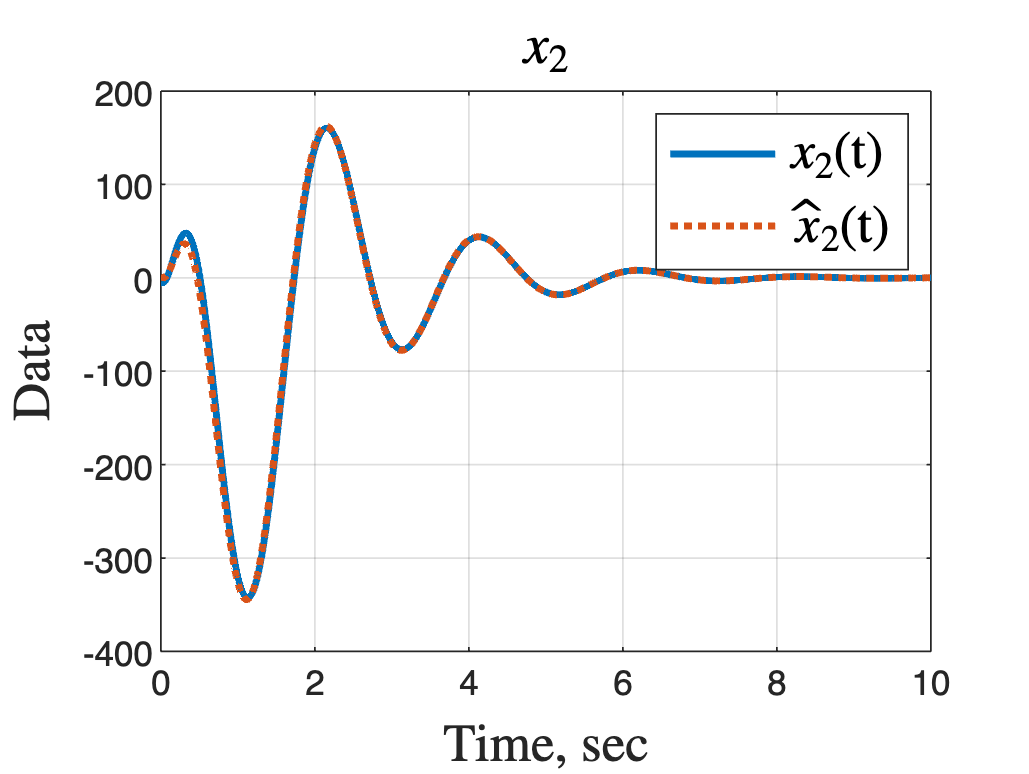

grid on;
hold off;

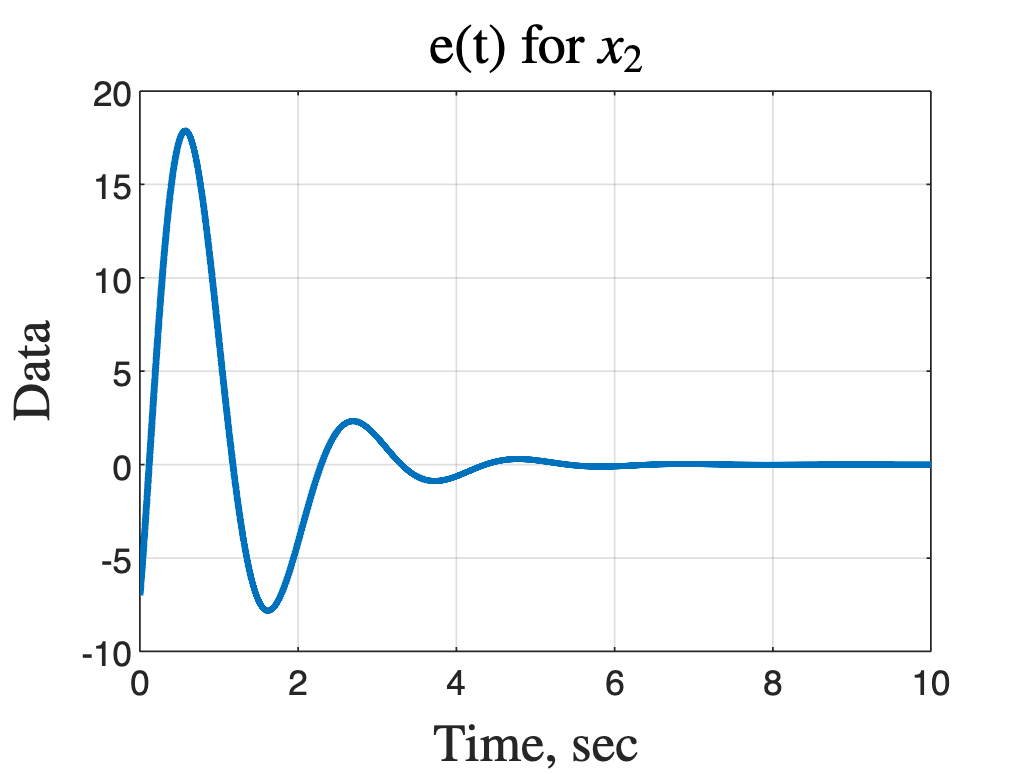


plot(out.e.Time,out.e.Data(:,2), 'LineWidth', 2);
title('e(t) for $x_{2}$','Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 15);
xlabel('Time, sec', 'Interpreter', 'latex', 'FontSize', 15);
grid on;
hold off;


plot(out.x.Time,out.x.Data(:,3), 'LineWidth', 2);
hold on;
plot(out.x1.Time,out.x1.Data(:,3), 'LineWidth', 2, 'LineStyle',':');
title('$x_{3}$','Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 15);
xlabel('Time, sec', 'Interpreter', 'latex', 'FontSize', 15);
legend("$x_{3}$(t)","$\hat{x}_{3}$(t)", "$x_{4}$", 'Interpreter', 'latex', 'FontSize', 15);

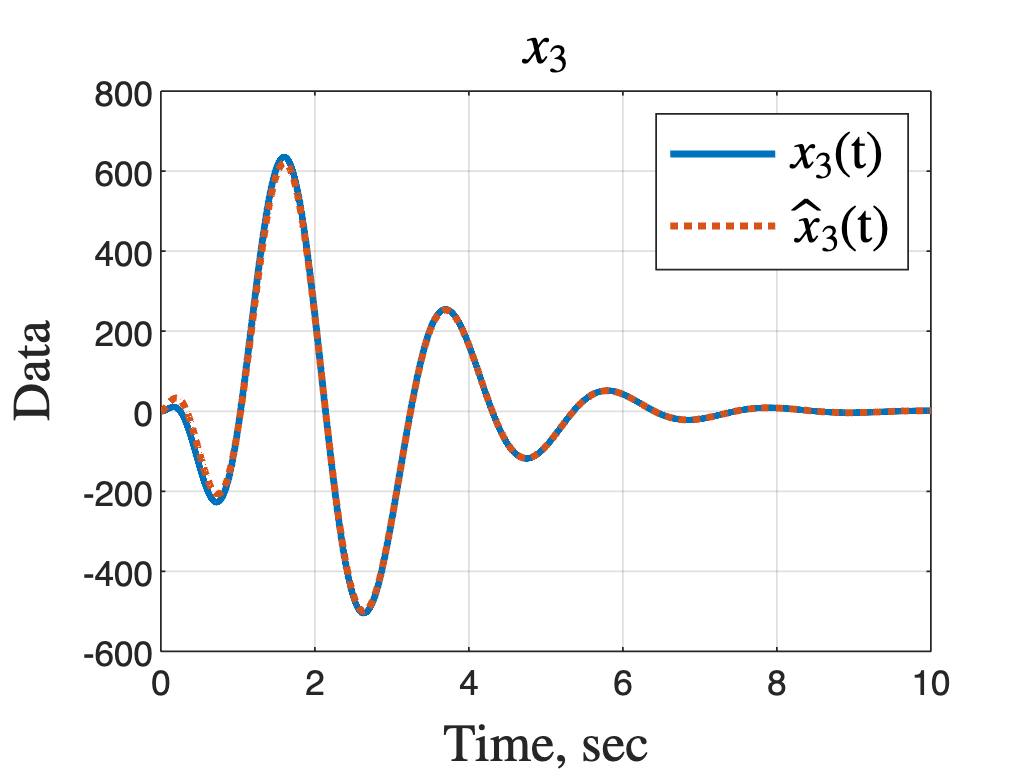

grid on;
hold off;

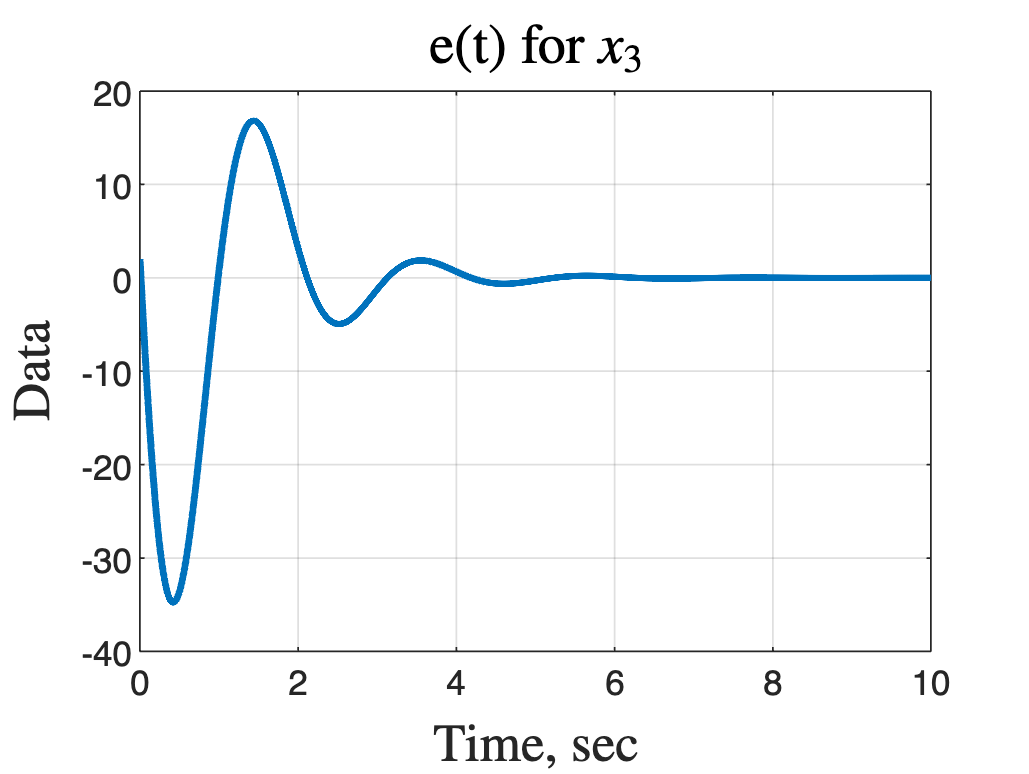


plot(out.e.Time,out.e.Data(:,3), 'LineWidth', 2);
title('e(t) for $x_{3}$','Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 15);
xlabel('Time, sec', 'Interpreter', 'latex', 'FontSize', 15);
grid on;
hold off;


plot(out.x.Time,out.x.Data(:,4), 'LineWidth', 2);
hold on;
plot(out.x1.Time,out.x1.Data(:,4), 'LineWidth', 2, 'LineStyle',':');
title('$x_{4}$','Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 15);
xlabel('Time, sec', 'Interpreter', 'latex', 'FontSize', 15);
legend("$x_{4}$(t)","$\hat{x}_{4}$(t)", "$x_{4}$", 'Interpreter', 'latex', 'FontSize', 15);

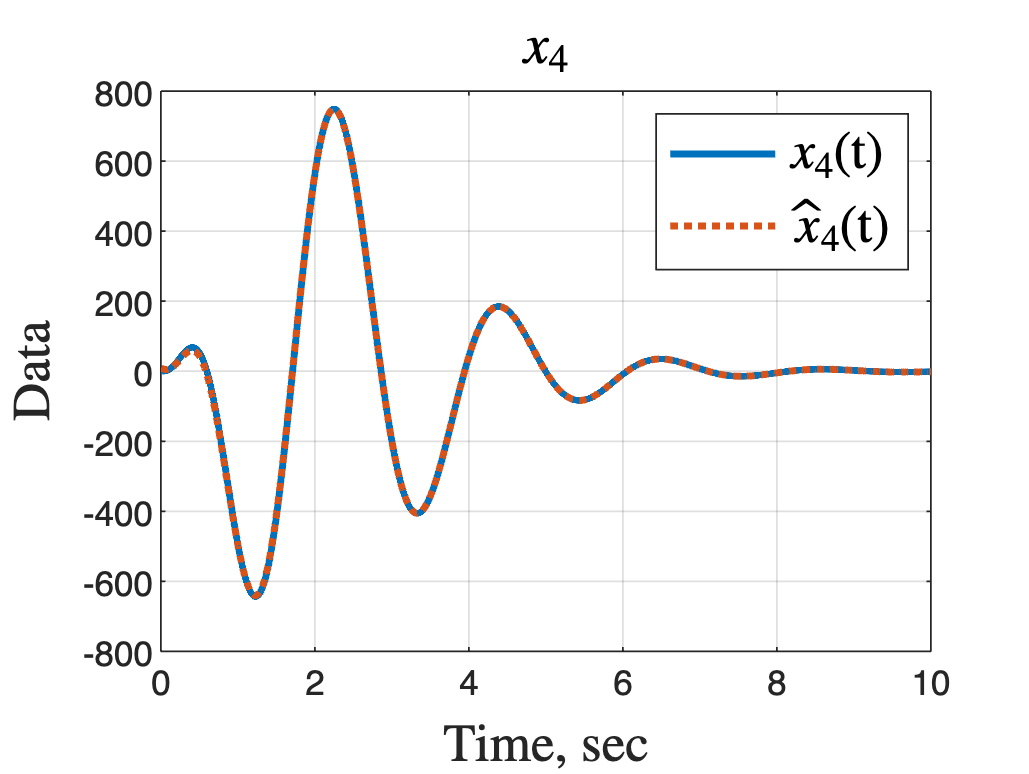

grid on;
hold off;

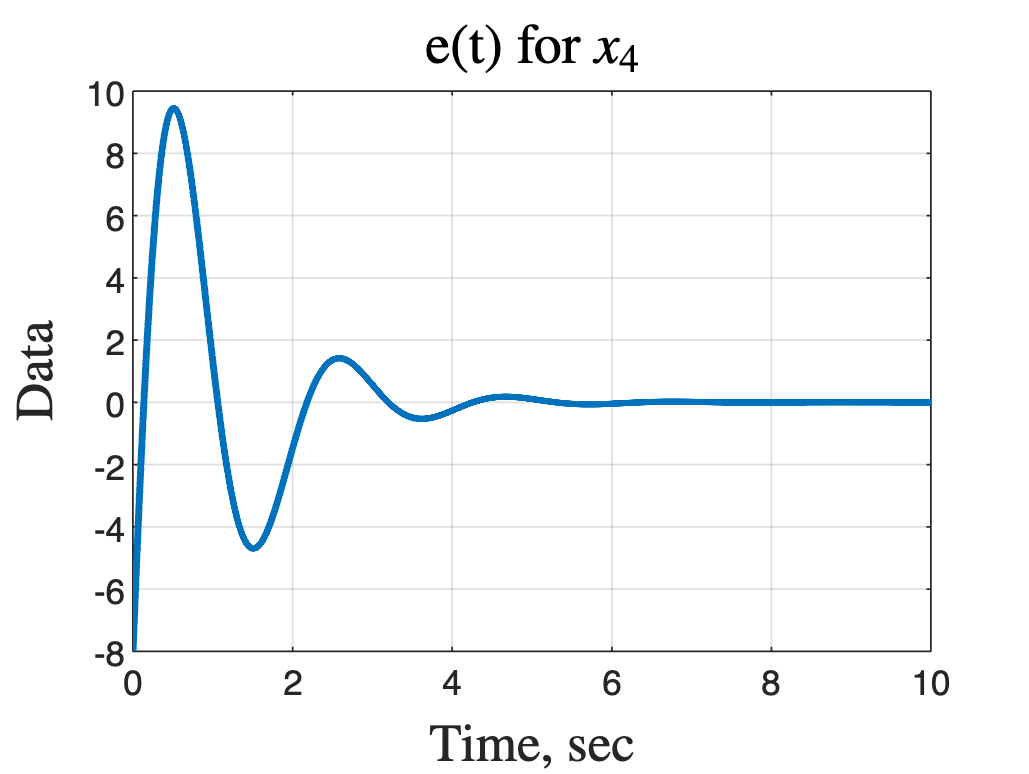


plot(out.e.Time, out.e.Data(:,4), 'LineWidth', 2);
title('e(t) for $x_{4}$','Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 15);
xlabel('Time, sec', 'Interpreter', 'latex', 'FontSize', 15);
grid on;
hold off;


plot(out.y.Time, out.y.Data(:,1), 'LineWidth', 2);
hold on;
plot(out.y1.Time,out.y1.Data(:,1), 'LineWidth', 2, 'LineStyle',':');
title('$y_{1}$','Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 15);
xlabel('Time, sec', 'Interpreter', 'latex', 'FontSize', 15);
legend("$y_{1}$(t)","$\hat{y}_{1}$(t)", "$x_{4}$", 'Interpreter', 'latex', 'FontSize', 15);

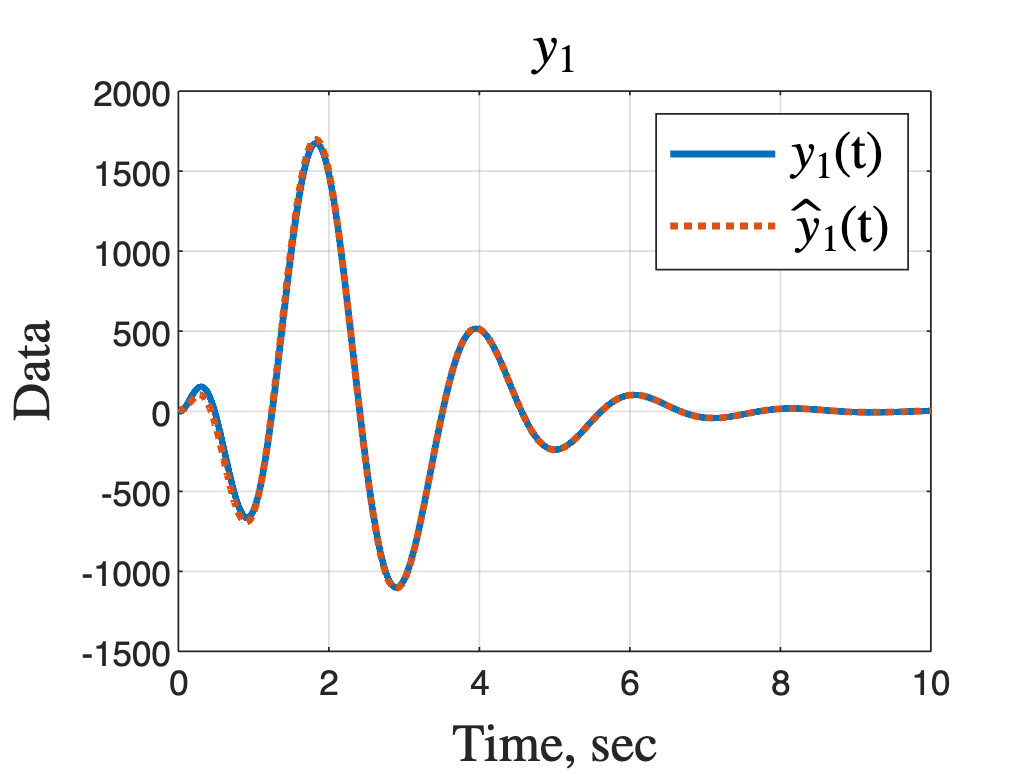

grid on;
hold off;


plot(out.y.Time, out.y.Data(:,2), 'LineWidth', 2);
hold on;
plot(out.y1.Time,out.y1.Data(:,2), 'LineWidth', 2, 'LineStyle',':');
title('$y_{2}$','Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 15);
xlabel('Time, sec', 'Interpreter', 'latex', 'FontSize', 15);
legend("$y_{2}$(t)","$\hat{y}_{2}$(t)", "$x_{4}$", 'Interpreter', 'latex', 'FontSize', 15);

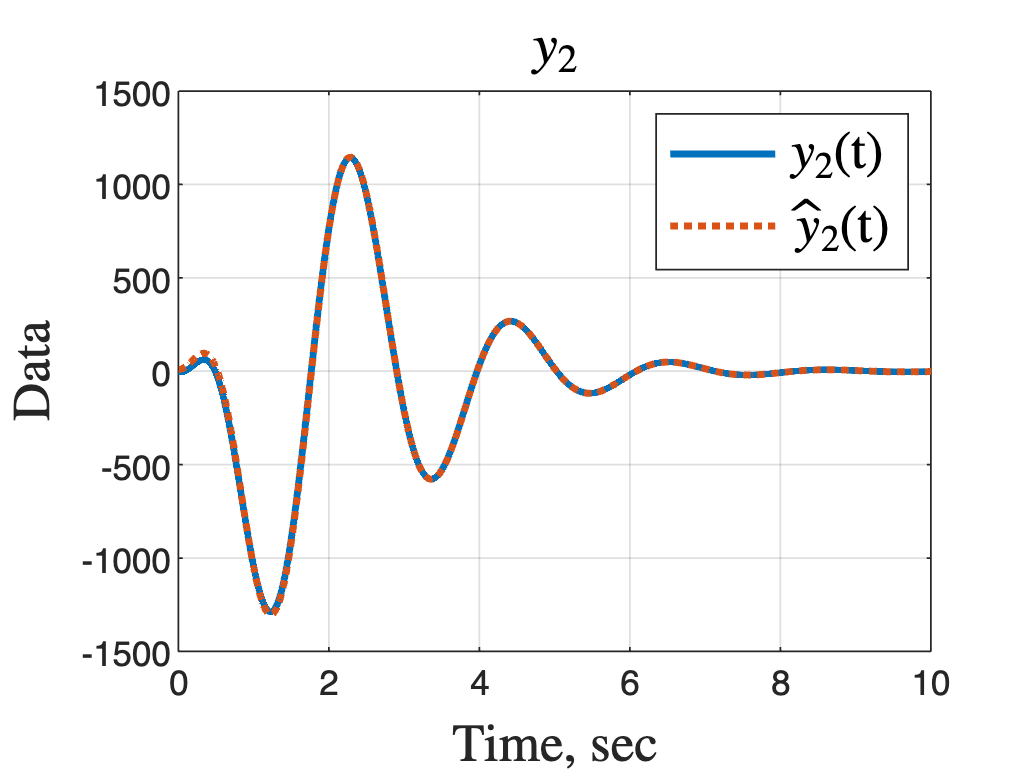

grid on;
hold off;

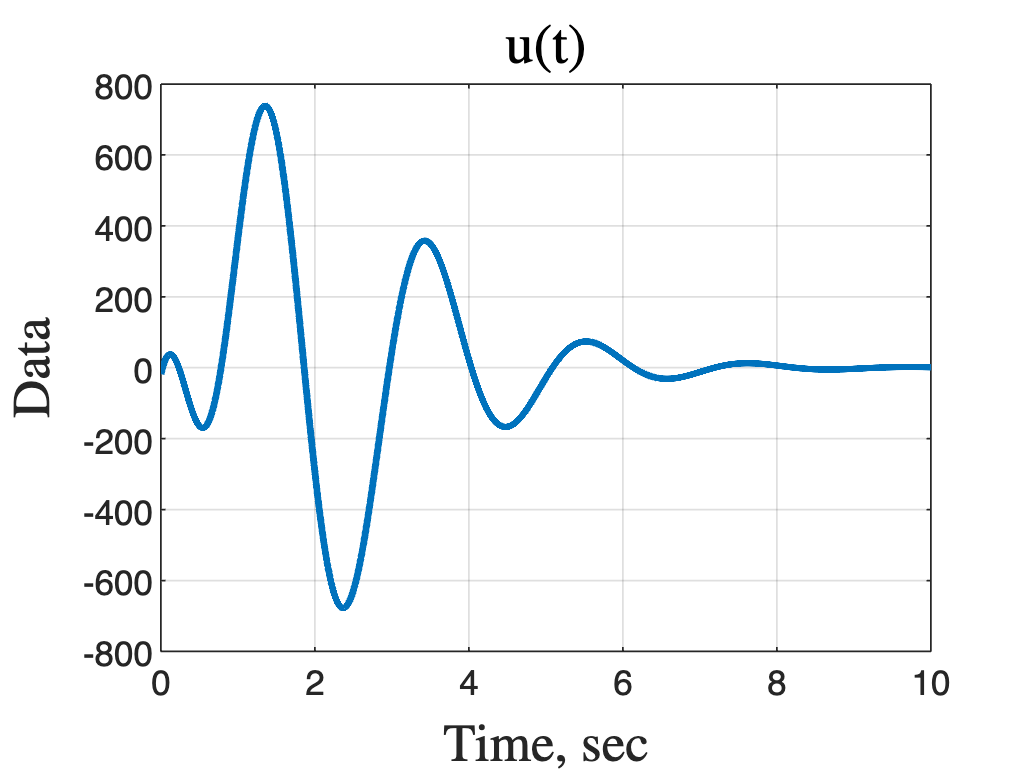


plot(out.u, 'LineWidth', 2);
title('u(t)','Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 15);
xlabel('Time, sec', 'Interpreter', 'latex', 'FontSize', 15);
grid on;